## NASA Turbofan Level B2: Understand your data and your modelling goal

clc; close all; clear all; 

### Load data and extract sensor measurements

raw_train_data = dataloader('NASA-Turbofan-data\train_FD001.txt');

% Take Sensor17 column (it will be the target variable)
targetVariable = raw_train_data.Sensor17;
raw_train_data.Sensor17 = [];

disp('Show dataset of sensor measurements (rows as observations, columns as sensor values)')

Show dataset of sensor measurements (rows as observations, columns as sensor values)


raw_train_data_sensors = raw_train_data( ...
    :, startsWith(raw_train_data.Properties.VariableNames, "Sensor") ...
)

raw_train_data_sensors = 20631×20 table
    Sensor1    Sensor2    Sensor3    Sensor4    Sensor5    Sensor6    Sensor7    Sensor8    Sensor9    Sensor10    Sensor11    Sensor12    Sensor13    Sensor14    Sensor15    Sensor16    Sensor18    Sensor19    Sensor20    Sensor21
    _______    _______    _______    _______    _______    _______    _______    _______    _______    ________    ________    ________    ________    ________

### Check missing values

disp('Show rows of dataset with missing values')

Show rows of dataset with missing values


rowsWithMissing = any(ismissing(raw_train_data), 2);
missingRows = raw_train_data(rowsWithMissing, :)


missingRows =

  0×25 empty table

    Unit    Cycle    OpSet1    OpSet2    OpSet3    Sensor1    Sensor2    Sensor3    Sensor4    Sensor5    Sensor6    Sensor7    Sensor8    Sensor9    Sensor10    Sensor11    Sensor12    Sensor13    Sensor14    Sensor15    Sensor16    Sensor18    Sensor19    Sensor20    Sensor21
    ____    _____    ______    ______    ______    _______    _______    

### Units cycles histogram

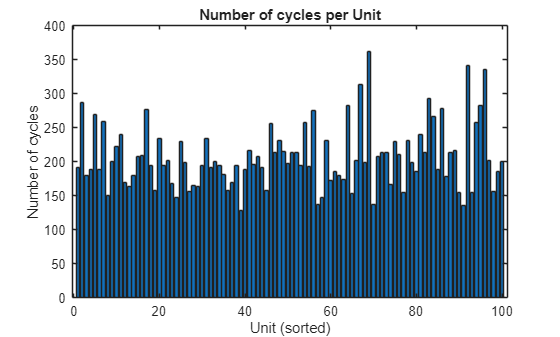

% Get the list of unique units, sorted
units = unique(raw_train_data.Unit, 'sorted');

% Count the number of rows (cycles) for each unit
cycleCounts = zeros(size(units));
for i = 1:numel(units)
    cycleCounts(i) = sum(raw_train_data.Unit == units(i));
end

% Plot a bar graph
bar(cycleCounts)
xlabel('Unit (sorted)')        % x-axis = unit number
ylabel('Number of cycles')     % y-axis = number of rows for that unit
title('Number of cycles per Unit')

### Sensors observations distributions

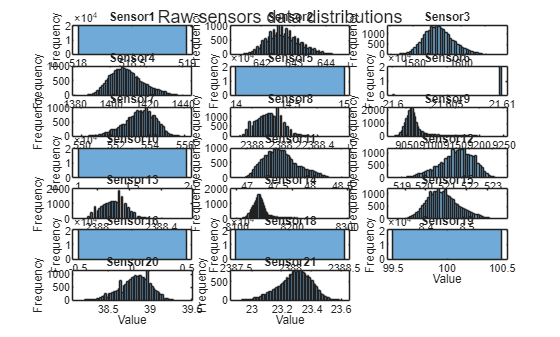

%% Extract sensor column names
% Get all variable names from the sensor table
sensorCols = raw_train_data_sensors.Properties.VariableNames;

% Number of sensors
nSensors = numel(sensorCols);

% Define subplot grid (3 columns)
cols = 3;
rows = ceil(nSensors / cols);

%% Plot histogram for each sensor
figure;
for i = 1:nSensors
    subplot(rows, cols, i)                           % create subplot
    histogram(raw_train_data_sensors.(sensorCols{i})) % plot histogram for current sensor
    xlabel('Value')                                  % x-axis label
    ylabel('Frequency')                              % y-axis label
    title(sensorCols{i})                             % individual subplot title
end

% Add a super title for the entire figure
sgtitle('Raw sensors data distributions')          


%% Initialize table to store basic statistics for each sensor
stats = table('Size',[nSensors 8], ...
              'VariableTypes', {'string','double','double','double','double','double','double','double'}, ...
              'VariableNames', {'Sensor','Mean','Median','Std','Min','Q25','Q75','Max'});

%% Compute statistics for each sensor
for i = 1:nSensors
    colData = raw_train_data_sensors.(sensorCols{i});  % select current sensor column
    
    stats.Sensor(i) = sensorCols{i};                  % sensor name
    stats.Mean(i) = mean(colData, 'omitnan');        % mean, ignoring NaN
    stats.Median(i) = median(colData, 'omitnan');    % median, ignoring NaN
    stats.Std(i) = std(colData, 'omitnan');          % standard deviation, ignoring NaN
    stats.Min(i) = min(colData);                     % minimum value
    stats.Q25(i) = prctile(colData, 25);            % 25th percentile
    stats.Q75(i) = prctile(colData, 75);            % 75th percentile
    stats.Max(i) = max(colData);                     % maximum value
end

%% Display the statistics table
disp(stats)

      Sensor       Mean     Median       Std         Min       Q25       Q75       Max  
    __________    ______    ______    __________    ______    ______    ______    ______

    "Sensor1"     518.67    518.67    3.8086e-11    518.67    518.67    518.67    518.67
    "Sensor2"     642.68    642.64       0.50005    641.21    642.32       643    644.53
    "Sensor3"     1590.5    1590.1        6.1311      1571    1586.3    1594.4    1616.9
    "Sensor4"     1408.9      1408        9.0006    1382.2    1402.4    1414.6    1441.5
    "Sensor5"      14.62     14.62     3.837e-13     14.62     14.62     14.62     14.62
    "Sensor6"      21.61     21.61      0.001389      21.6     21.61     21.61     21.61
    "Sensor7"  

### Sensors correlations

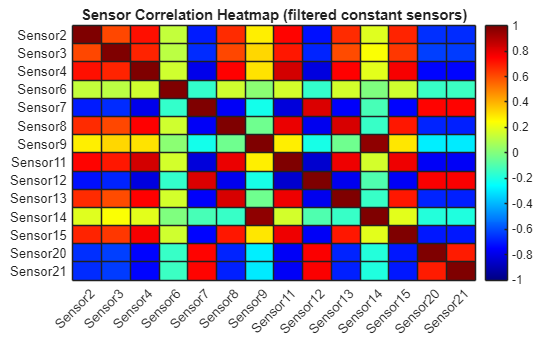

%% Extract numeric sensor data
sensorData = raw_train_data_sensors{:,:};  % convert table to numeric matrix
sensorNames = raw_train_data_sensors.Properties.VariableNames;

%% Identify near-constant sensors
% Compute standard deviation for each sensor
stdDev = std(sensorData, 0, 1);

% Define threshold for near-constant sensors
threshold = 1e-6;

% Keep only sensors with enough variability
keepCols = stdDev > threshold;
sensorDataFiltered = sensorData(:, keepCols);
sensorNamesFiltered = sensorNames(keepCols);

%% Compute correlation matrix
corrMatrix = corr(sensorDataFiltered, 'Rows', 'complete');

%% Plot heatmap
figure;
heatmap(sensorNamesFiltered, sensorNamesFiltered, corrMatrix, ...
        'Colormap', jet, ...           % set color map
        'ColorLimits', [-1 1], ...     % correlation range
        'ColorbarVisible', 'on');      % show colorbar
title('Sensor Correlation Heatmap (filtered constant sensors)');

### Exploratory data analysis (EDA) using PCA

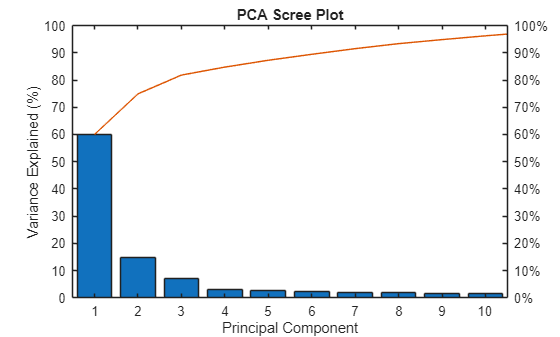

% remove near-constant sensors
stdDev = std(sensorData, 0, 1);
threshold = 1e-6;
keepCols = stdDev > threshold;
sensorDataFiltered = sensorData(:, keepCols);
sensorNamesFiltered = sensorNames(keepCols);

% standardize data (mean=0, std=1)
sensorDataStd = zscore(sensorDataFiltered);

% Perform PCA
[coeff, score, latent, tsquared, explained] = pca(sensorDataStd);
% coeff: principal component loadings (sensors x PCs)
% score: principal component scores (observations x PCs)
% latent: eigenvalues of covariance matrix
% explained: percentage of variance explained by each PC

% Scree plot (variance explained)
figure;
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')
title('PCA Scree Plot')

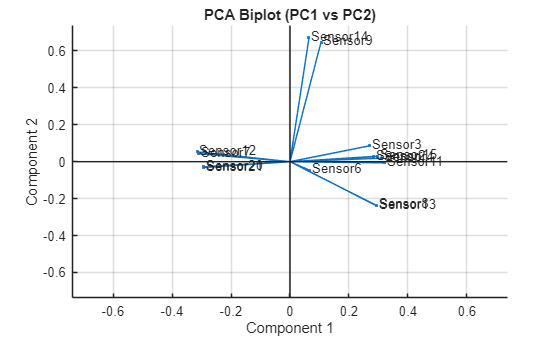


% Biplot (scores and loadings), first two principal components
figure;
biplot(coeff(:,1:2), 'VarLabels', sensorNamesFiltered);
title('PCA Biplot (PC1 vs PC2)')

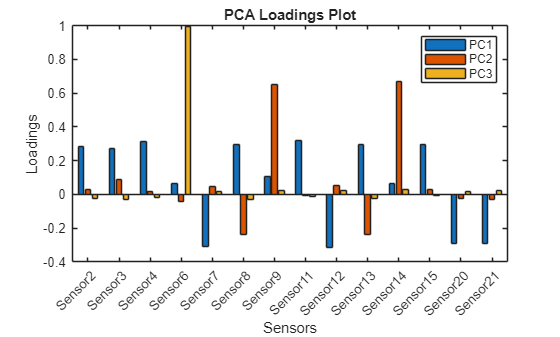


% Plot loadings for first few PCs
figure;
bar(coeff(:,1:3))
set(gca, 'XTickLabel', sensorNamesFiltered, 'XTickLabelRotation', 45)
xlabel('Sensors')
ylabel('Loadings')
legend('PC1','PC2','PC3')
title('PCA Loadings Plot')

### T2 outliers detection

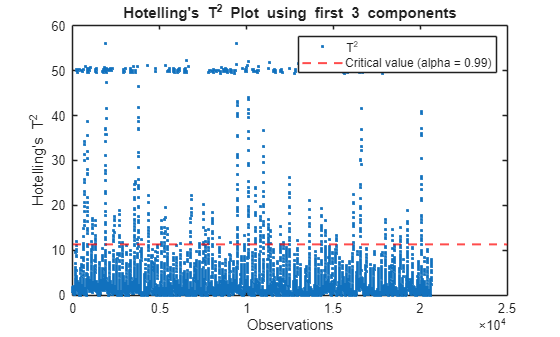

% Number of observations
[n, m] = size(sensorDataStd);

% Choose number of principal components manually
k = 3;

% Compute Hotelling's T² using the first k components
T2 = sum((score(:,1:k).^2) ./ latent(1:k)', 2);

% Critical value for Hotelling's T² (99% confidence level)
alpha = 0.99;
Fcrit = finv(alpha, k, n - k);
T2crit = k*(n-1)*(n+1)/(n*(n-k)) * Fcrit;

% Plot Hotelling's T² for each observation
figure;
plot(T2, '.'); hold on;
yline(T2crit, 'r--', 'LineWidth', 1.5);
xlabel('Observations');
ylabel('Hotelling''s T^2');
title(sprintf('Hotelling''s T^2 Plot using first %d components', k));
legend('T^2', 'Critical value (alpha = 0.99)');


percent_below = mean(T2 < T2crit) * 100;
fprintf('%.2f %% of observations are below the critical limit.\n', percent_below);

95.75 % of observations are below the critical limit.
